Load the data

[x, y] = bodyfat_dataset();

Normalization of features

for i = 1:13
    x(i, :) = (x(i, :)-min(x(i, :)))/(max(x(i, :))-min(x(i, :)));
end

Train ANN

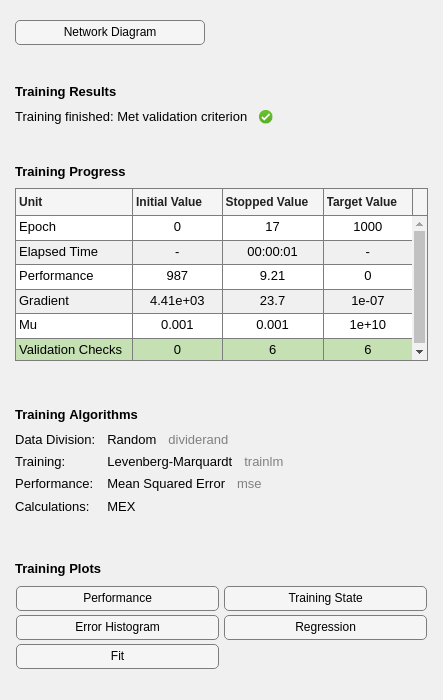

hiddenLayerSize = 10;
net = fitnet(hiddenLayerSize, 'trainlm');
net.divideParam.trainRatio = 0.70;
net.divideParam.testRatio = 0.15;
net.divideParam.valRatio = 0.15;

[net, tr] = train(net, x, y);

Performance of the ANN network

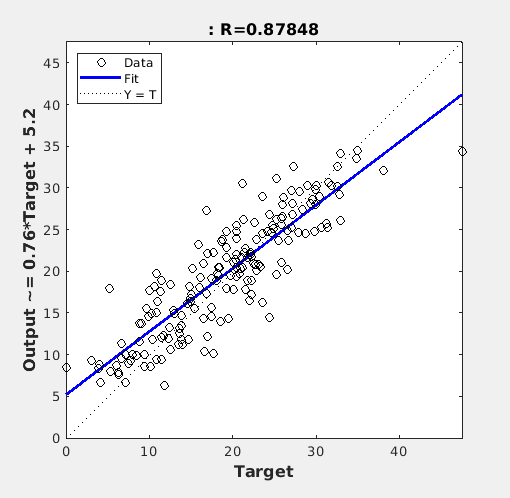

yTrain = net(x(:, tr.trainInd));
yTrainTrue = y(tr.trainInd);

%{
disp(yTrain);
disp(yTrainTrue);
%}

figure, plotregression(yTrainTrue, yTrain);


%{
SSR = sum((yTrain-yTrainTrue).^2);
TSS = sum(((yTrainTrue - mean(yTrainTrue)).^2));

R = sqrt(1 - (SSR/TSS));
disp(R);
%}

[rX,~,~] = regression(yTrainTrue, yTrain, "one");
disp(rX);

    0.8785




%{
rmseTrain = sqrt(mean((yTrain - yTrainTrue).^2));
disp(rmseTrain);
yVal = net(x(:, tr.valInd));
yValTrue = y(tr.valInd);
rmseVal = sqrt(mean((yVal - yValTrue).^2));
disp(rmseVal);
yTest = net(x(:, tr.testInd));
yTestTrue = y(tr.testInd);
rmseTest = sqrt(mean((yTest - yTestTrue).^2));
disp(rmseTest);
%}